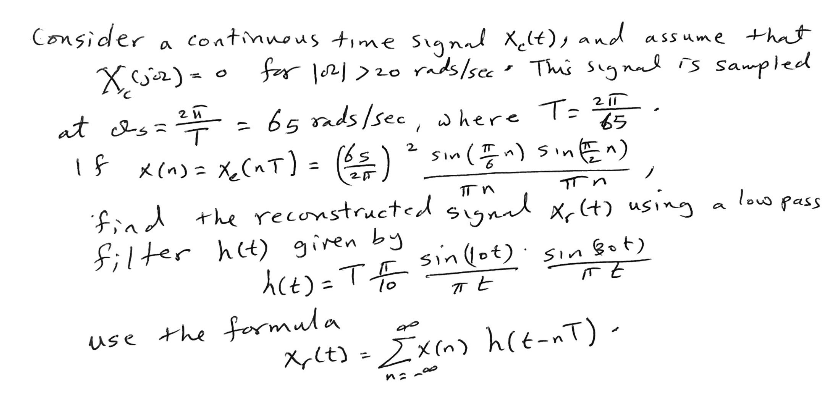

The sampling frequency is deffinitely more than twice the maximum frequency of x, so it can be sampled properly.

% Generate plot of x
T = 2*pi/65;
n = 0:T:20;

n =          0    0.0967    0.1933    0.2900    0.3867    0.4833    0.5800    0.6767    0.7733    0.8700    0.9666    1.0633    1.1600    1.2566    1.3533    1.4500    1.5466    1.6433    1.7400    1.8366    1.9333    2.0300    2.1266    2.2233    2.3199    2.4166    2.5133    2.6099    2.7066    2.8033    2.8999    2.9966    3.0933    3.1899    3.2866    3.3833    3.4799    3.5766    3.6732    3.7699    3.8666    3.9632    4.0599    4.1566    4.2532    4.3499    4.4466    4.5432    4.6399    4.7366


n = n(2:end);

n =     0.0967    0.1933    0.2900    0.3867    0.4833    0.5800    0.6767    0.7733    0.8700    0.9666    1.0633    1.1600    1.2566    1.3533    1.4500    1.5466    1.6433    1.7400    1.8366    1.9333    2.0300    2.1266    2.2233    2.3199    2.4166    2.5133    2.6099    2.7066    2.8033    2.8999    2.9966    3.0933    3.1899    3.2866    3.3833    3.4799    3.5766    3.6732    3.7699    3.8666    3.9632    4.0599    4.1566    4.2532    4.3499    4.4466    4.5432    4.6399    4.7366    4.8332


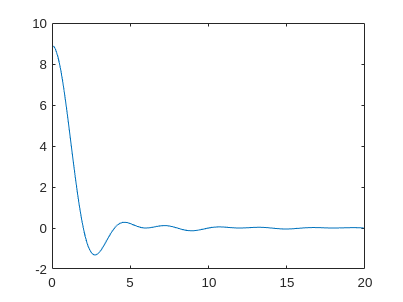

x = ((1/T)^2)*(sin(pi*n/6).*sin(pi*n/2))./((pi*n).^2);
plot(n, x)

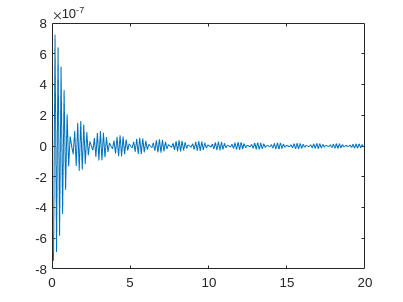


%Generate Plot of h
h = (pi*T/10)*(sin(10*n)/(pi*n)).*(sin(30*n)./(pi*n));
plot(n, h)


% Take the fft of h and x and plot them
X = fft(x);0.0001

ans = 1.0000e-04

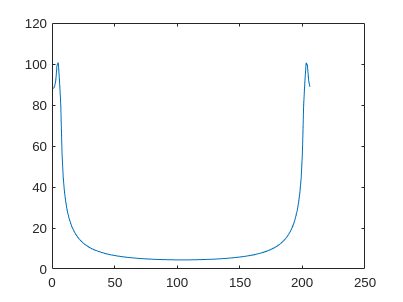

H = fft(h);
plot(abs(X))

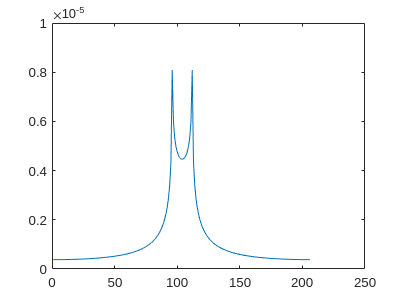

plot(abs(H))

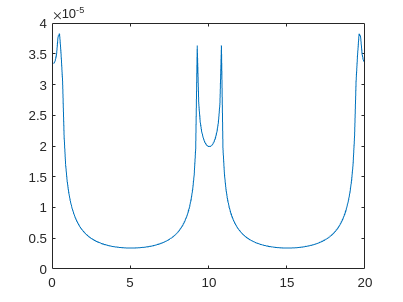


% convolve and plot the frequency result
X_r = X.*H;
plot(n,abs(X_r))

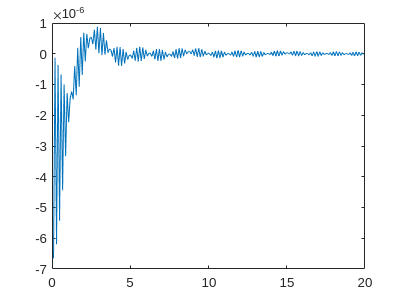

% plot the convolution in the time domain
x_r = ifft(X_r);
plot(n,x_r)